# Analisi Algoritmo di Bisezione 

In questa documentazione si mostreranno i casi di test relativi all'algoritmo di bisezione.

# Test di accuratezza

Il  test di accuratezza determina quanto la soluzione approssimata trovata attraverso il metodo di bisezione si avvicina alla soluzione dell'algoritmo fzero(). Quest'ultimo è il migliore algoritmo utilizzato per ffff lo zero in Matlab. Ai fini del calcolo dell' accuratezza è stata implementata la funzione CalcoloAccuratezza() . Essa calcola l'errore relativo tra le soluzioni restituite dai due algoritmi al medesimo problema. Una breve documentazione e l'implementazione della funzione è disponibile: 

doc CalcoloAccuratezza

## **Esempio**

Calcolare lo zero  di $2-e^{-x} \;-\sqrt{x}$ nell'intervallo $\left\lbrack 0,4\right\rbrack$ al variare della tolleranza TOL inserita dall'utente supponendo NMAX di default.

`Command line Matlab`

f = @(x)(2-exp(-x)-sqrt(x));
x0 = [0 4];

CalcoloAccuratezza(f,x0,1e-10)

ans =      4.554423086560188e-11


CalcoloAccuratezza(f,x0,1e-11)

ans =      1.768375924351608e-12


CalcoloAccuratezza(f,x0,1e-12)

ans =      3.766887616493818e-13


CalcoloAccuratezza(f,x0,1e-13)

ans =      2.265115824710654e-16


CalcoloAccuratezza(f,x0,1e-14)

ans =      2.265115824710654e-16


CalcoloAccuratezza(f,x0,1e-15)

ans =      2.265115824710654e-16


CalcoloAccuratezza(f,x0,eps)

ans =      2.265115824710654e-16


`Esecuzione da interfaccia grafica`

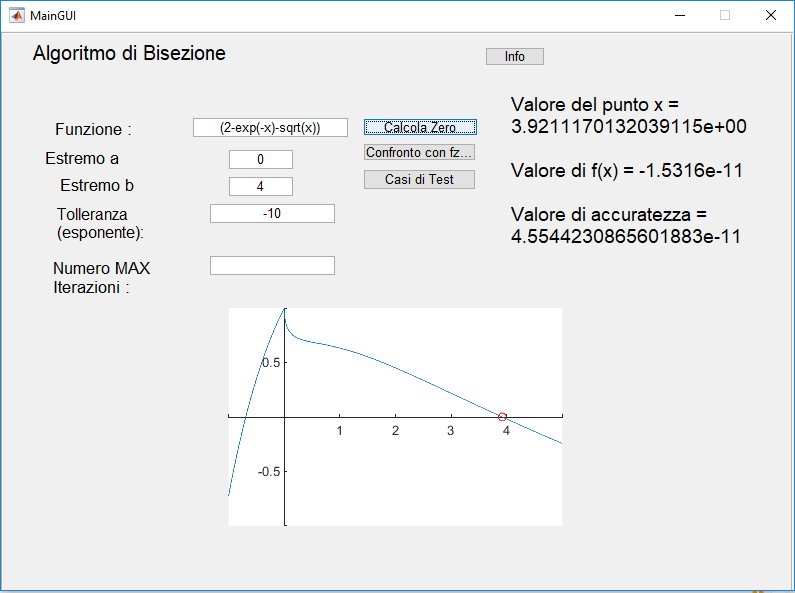

# Valutazione Performance

Si è implementata una funzione che crea un grafico di confronto tra i due algoritmi sopra citati. Si è calcolata la performance confrontando il numero di iterazioni necessarie all'algoritmo di Bisezione con quelle necessarie alla funzione fzero() considerata la tolleranza richiesta. 

## **Esempio**

Calcola la performance dell'algoritmo di bisezione quando è in input f=  di $2-e^{-x} \;-\sqrt{x}$ nell'intervallo $\left\lbrack 0,4\right\rbrack$ al variare della tolleranza TOL inserita dall'utente supponendo NMAX di default.L La funzione restituirà un grafico di confronto tra i due approcci.

`Command line Matlab`

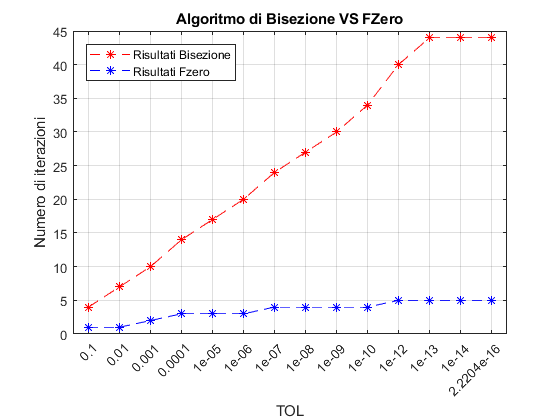

f = @(x) (2-exp(-x)-sqrt(x));%funzione handle
warning('off');
xo = [0 4];
TOL=[10.^-1 10.^-2 10.^-3  10.^-4 10.^-5 10.^-6 10.^-7 10.^-8 10.^-9 10.^-10 10.^-12 10.^-13 10.^-14 eps];
Valuta_Performance(f,x0,TOL);

`Esecuzione da interfaccia grafica`

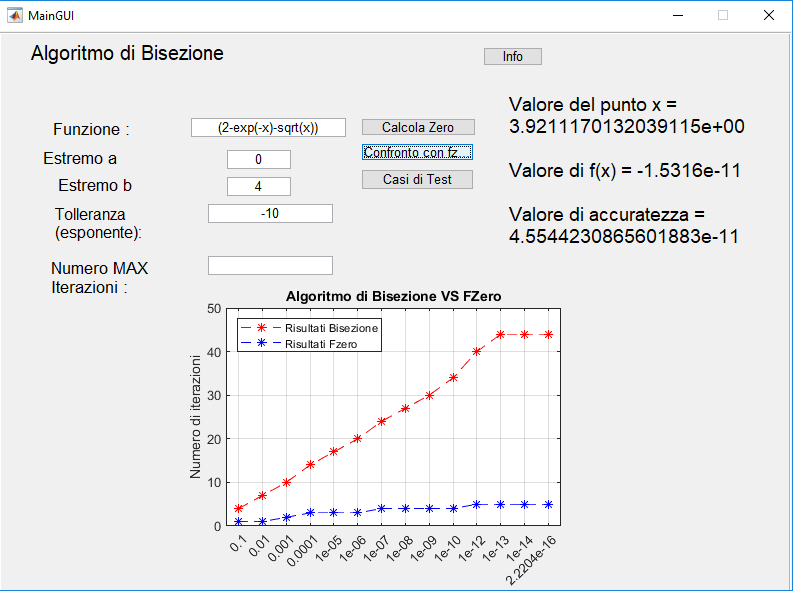

Come si nota dal grafico il numero di iterazioni richieste dalla funzione fzero() è minore rispetto a quelle della funzione algoritmo_di_bisezione() per ogni valore di TOL. Si può osservare che la differenza tra i due approcci è tanto più marcata quanto più si cerca una risoluzione migliore diminuendo la tolleranza.

# Test di robustezza

Per valutare la robustezza dell'algoritmo è stata implementata una test suite. I casi di test sono stati scelti a partire dalle condizioni di errore o warning che possono avere luogo. Ogni caso di test lo descriveremo brevemente a partire dai parametri di input e dalla funzionalità che  viene testata. Il numero di casi di test è: 15 ,implementati in una classe definita dal matlab matlab.unittest.TestCase inserendo al suo interno un costruttore che riceve i parametri della funzione che la test suite deve testare. In tal modo si è automatizzato il processo di esecuzione dei test. Le istruzioni per eseguire i test saranno mostrate successivamente.

Il sistema esegue in automatico i test, riportando in tabella i test eseguiti con successo e quelli senza successo. 

Di seguito seguono i casi di test più rilevanti che sono stati effettuati. La funzione da testare sarà generata da linea di comando e passata alla test suite.

## Test case 4

 Verifica l'errore nel caso in cui il primo estremo o il secondo estremo dell'intervallo inserito non è un numero.

## Input

- **f **=  $xˆ2-4$

- **x0** =$\left\lbrack 0\text{ }\mathrm{'a'}\right\rbrack$

- **TOL** = ${10}^{-15}$

- **NMAX** =$600$;

## Test case 6

 Verifica l'errore nel caso in cui entrambi i valori dell'intervallo x0 siano uguali.

## Input

- **f **=  $xˆ2-4$

- **x0** =$\left\lbrack 3\text{ }3\right\rbrack$

- **TOL** = ${10}^{-15}$

- **NMAX** =$600$;

## Test case 7

Verifica l'errore nel caso in cui non è soddisfatto il teorema degli zeri.

## Input

- **f **=  $xˆ2-4$

- **x0** =$\left\lbrack -3\text{ }3\right\rbrack$

- **TOL** = ${10}^{-15}$

- **NMAX** =$600$;

## Test case 8

Verifica che la tolleranza sia stata inserita o meno dall'utente.

## Input

- **f **=  $xˆ2-4$

- **x0** =$\left\lbrack 0\text{ }4\right\rbrack$

- **TOL** = non inserito

- **NMAX** =$\mathrm{non}\text{ }\mathrm{inserito}$

## Test case 9

Si verifica se la tolleranza inserita è minore di eps.

## Input

- **f **=  $xˆ2-4$

- **x0** =$\left\lbrack 0\text{ }4\right\rbrack$

- **TOL** = $-1$

- **NMAX** =$600$;

## Test case 16

Verifica se l'accuratezza è adeguata  a partire da una determinata tolleranza TOL.

## Input

- **f **=  $xˆ2-4$

- **x0** =$\left\lbrack 0\text{ }4\right\rbrack$

- **TOL** = ${10}^{-15}$

- **NMAX** =$600$;

## Test case 11

Verifica se il valore di NMAX  non è numerico, scalare,infinito oppure NaN.

## Input

- **f **=  $xˆ2-4$

- **x0** =$\left\lbrack 0\text{ }4\right\rbrack$

- **TOL** = ${10}^{-15}$

- **NMAX** =$\mathrm{'a'}$;

## Caso di test 13                                                                                                                   

Verifica se il valore di NMAX è minore o uguale a 2.

## Input

- **f **=  $xˆ2-4$

- **x0** =$\left\lbrack 0\text{ }4\right\rbrack$

- **TOL** = ${10}^{-15}$

- **NMAX** =$1$;

## Caso di test 15                                                                                                                      

 Verifica se si è superato il numero massimo di iterazioni per determinare l'uscita. Non sarà trovato lo zero.

## Input

- **f **=  $xˆ2-4$

- **x0** =$\left\lbrack 0\text{ }4\right\rbrack$

- **TOL** = ${10}^{-15}$

- **NMAX** =$3$;

##    Esecuzione  Test suite

Si considera ora l'esecuzione della test suite a partire dagli input precedenti.

result1 = runtests('TEST_RICHIAMA_PARAMETRI.m');

Running TEST_RICHIAMA_PARAMETRI
.....
Verification failed in TEST_RICHIAMA_PARAMETRI/TestCase8.

    ---------------------
    Framework Diagnostic:
    ---------------------
    verifyWarning failed.
    --> The function handle did not issue any warnings.
        
        Expected Warning:
            --> 'WARN:TolleranzaNonInserita'
    
    Evaluated Function:
      function_handle with value:
    
        @()algoritmo_di_bisezione(f,x0)

    ------------------
    Stack Information:
    ------------------
    In C:\Users\peppe\github\elaborato1_matlab\TEST_RICHIAMA_PARAMETRI.m (TEST_RICHIAMA_PARAMETRI.TestCase8) at 71

table(result1)

ans = 15×6 table
                    Name                    Passed    Failed    Incomplete          Duration            Details   
    ____________________________________    ______    ______    __________    ____________________    ____________

    'TEST_RICHIAMA_PARAMETRI/TestCase3'     true      false     false         2.40209572511267e-02    [1×1 struct]
    'TEST_RICHIAMA_PARAMETRI/TestCase4'     true      false     false         3.15259508353192e-01    [1×1 struct]
    'TEST_RICHIAMA_PARAMETRI/TestCase5'     true      false     false         8.63882164055043e-03    [1×1 struct]
    'TEST_RICHIAMA_PARAMETRI/TestCase6'     true      false     false         6.88277087033748e-03    [1×1 struct]
    'TEST_RICHIAMA_PARAMETRI/TestCase7'     true      false     false         1.19091452

## Riferimenti                                                                                                                  

[1] *Robert D. Cameron, 2013, *[http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html](http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html)

[2] Matlab Documentation, [https://it.mathworks.com/help/matlab/function-based-unit-tests.html](https://it.mathworks.com/help/matlab/function-based-unit-tests.html)

## Autori                                                                                                                          

** Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936**